Create datastore

imds = imageDatastore("WormImages")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA01.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA02.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA03.tif'
                               ... and 90 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


groundtruth = readtable("WormData.csv")

groundtruth = 93×2 table
         File           Status  
    _______________    _________

    {'wormA01.tif'}    {'alive'}
    {'wormA02.tif'}    {'alive'}
    {'wormA03.tif'}    {'alive'}
    {'wormA04.tif'}    {'alive'}
    {'wormA05.tif'}    {'alive'}
    {'wormA06.tif'}    {'alive'}
    {'wormA07.tif'}    {'alive'}
    {'wormA08.tif'}    {'alive'}
    {'wormA09.tif'}    {'alive'}
    {'wormA10.tif'}    {'alive'}
    {'wormA11.tif'}    {'alive'}
    {'wormA12.tif'}    {'alive'}
    {'wormA13.tif'}    {'dead' }
    {'wormA14.tif'}    {'dead' }
    {'wormA15.tif'}    {'dead' }
    {'wormA16.tif'}    {'dead' }


imds.Labels = categorical(groundtruth.Status)

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA01.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA02.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA03.tif'
                               ... and 90 more
                              }
                      Labels: [alive; alive; alive ... and 90 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


Split images for training and testing

[traindata, testdata] = splitEachLabel(imds,0.6,"randomized")

traindata =   ImageDatastore with properties:

                       Files: {
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA01.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA04.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA07.tif'
                               ... and 53 more
                              }
                      Labels: [alive; alive; alive ... and 53 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


testdata =   ImageDatastore with properties:

                       Files: {
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA02.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA03.tif';
                              ' ...\MATLAB\deeplearning_course_files\Roundworms\WormImages\wormA05.tif'
                               ... and 34 more
                              }
                      Labels: [alive; alive; alive ... and 34 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


Creat augmented datastore for preprocessing

trainds= augmentedImageDatastore([227 227], traindata, "ColorPreprocessing", "gray2rgb")

trainds =   augmentedImageDatastore with properties:

             NumObservations: 56
                       Files: {56×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testds= augmentedImageDatastore([227 227], testdata, "ColorPreprocessing", "gray2rgb")

testds =   augmentedImageDatastore with properties:

             NumObservations: 37
                       Files: {37×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


Modify exsiting network

net = alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


builtlayers = net.Layers(1:end-3)

builtlayers =   22x1 Layer array with layers:

     1   'data'    Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0 

layers = [builtlayers;fullyConnectedLayer(2);softmaxLayer;classificationLayer]

layers =   25x1 Layer array with layers:

     1   'data'    Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
 

Training options

opts = trainingOptions("sgdm","InitialLearnRate",0.001)

opts =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 1.0000e-03
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
      GradientThresholdMethod: 'l2norm'
            GradientThreshold: Inf
                    MaxEpochs: 30
                MiniBatchSize: 128
                      Verbose: 1
             VerboseFrequency: 50
               ValidationData: []
          ValidationFrequency: 50
           ValidationPatience: Inf
                      Shuffle: 'once'
               CheckpointPath: ''
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'none'
               SequenceLength: 'longest'
         SequencePaddingValue: 0
     SequencePaddingDirection: 'right'
         DispatchInBackground: 0
      ResetInputNormalizat

Training

wormnet = trainNetwork(trainds,layers,opts)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       48.21% |       1.5594 |          0.0010 |
|      30 |          30 |       00:02:38 |      100.00% |       0.0100 |          0.0010 |
|========================================================================================|


wormnet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


Evaluate network with testdata 

pred = classify(wormnet,testds)

pred = 37×1 categorical array
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 


compare with reality

true = testdata.Labels

true = 37×1 categorical array
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 


Misclassification rate

mis = sum(pred ~= true)/numel(pred)

mis = 0

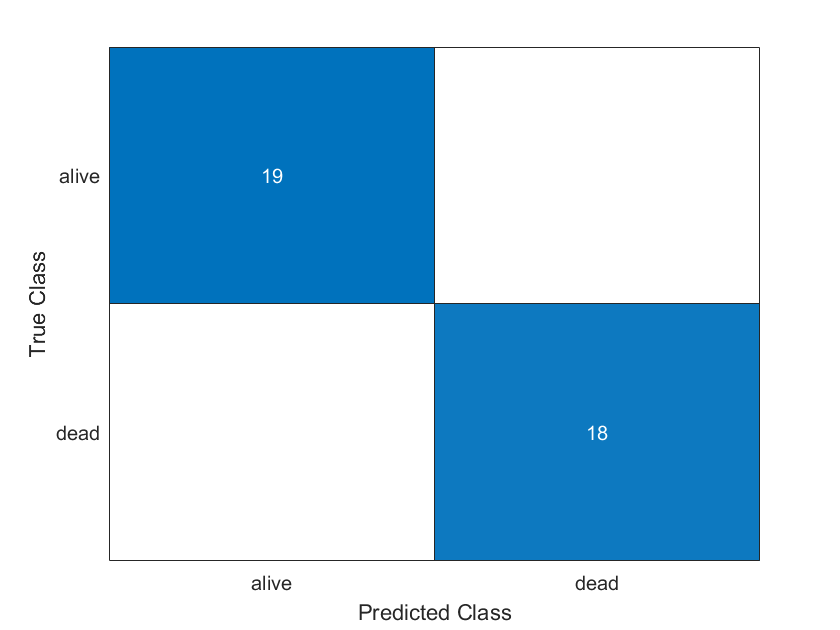

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


confusionchart(true,pred)